# AT-4

The goal of this circuit is to reduce the amplitude noise of a laser beam. Part of this laser will be directed to a photodiode and, after an appropriate amplification, it will be controlled by a digital PID module. 

%%(lines of code with an indent contain modifiable data)

We will use the OPA656 opamp to implement the 2 amplification stages. Its characteristics are

GBW = 230e6;
C_input_differential = 0.7e-12;
C_input_commonMode = 2.8e-12;
V_opamp_max = 3.5;

## stage1

transimpedence, gain g1 given by R_f1

max output given by the opamp saturation => limit on the max input current (and on the input laser intensity)

                                    laserPower_max = 80e-3; %better to put a higher max value than the expected max, you never know
                                    beamSplitterRatio = 1/100;

laserPowerOnDiode_max = laserPower_max * beamSplitterRatio;
photodiode_responsivity = 0.2;
photodiode_maxInput = 15e-3; %laserPowerOnDiode_max = photodiode_maxInput;
I_max = laserPowerOnDiode_max * photodiode_responsivity;

Let's choose the gain in order to have the max gain staying in the limits

Rf1 = V_opamp_max / I_max;
g1 = Rf1;

A feedback capacitance shoud be added to avoid a potential instability generated by the feedback resistor and the capacitance of the photodiode. Essentially, the parasitic capacitances create a zero at frequency $f_{\textrm{parasitic}} =\sqrt{\frac{\textrm{GBW}}{4\pi R_f C_{\textrm{tot}} }}$, where C_tot is the sum of all the capacitors in parallel on the inverting node. We want to add a pole at the same frequency, and so we choose Cf so that $\frac{1}{2\pi R_f C_f }=f_{\textrm{parasitic}}$

                                    C_parasitic_diode = 10e-12;

C_tot = C_parasitic_diode + C_input_differential + C_input_commonMode;
Cf = sqrt(C_tot / (pi * Rf1 * GBW));

## stage2

sum amplifier between output of stage1 and PWM output of redPitaya, the 2 inputs have different gains g2 and g_rp, given by the resistors R_f2, R_12 and R_rp. We can already set the value for g2

                                    g2 = 5;

The parallel of these resistors (as stated in the datasheet) should be less than 200 Ohm (the resistors create a pole with the parasitic input capacitance at the inverting node of the opamp. We should use a smaller value, so that the resistors will be smalll and will not increase the overall noise. Also, considering that the diode capacitance gets added to the parasitic input capacitance, we should reduce the parallel even more. The drawback would be a higher power consumption, and the opamp might not be able to erogate too much current.

                                    R_parallel = 180;%( < 200)

By changing the value from the redpitaya accordingly to the required laser intensity, at equilibrium the DC component of the output should always be 0, so that the AC component is free to move without exiting the redpitaya range of +-1V. So, with the max input, the redpitaya should output its max value to compensate that, and we can obtain the value for g_rp

V_rpMax = 1.8;
g_rp = I_max * g1 * g2 / V_rpMax;

At this stage, we could actually just give to the circuit the signal that would arrive to the redPitaya, since no actual digital conditioning of the signal is necessary. But, since future implementations could require the use of digital signals (ex: commands setn through Ethernet), it's better to already have the procedure prepared.

Now, knowing the values for the 2 gains, and knowing the limit on the parallel of the resistors, we can obtain the resistor values

%can't be bothered to do the calculations by hand. Thanks to fsolve() to let
%me be as lazy as I want
f_gain2 =    @(Rf, R12, R_rp) Rf - R12 * g2;
f_gain_rp =  @(Rf, R12, R_rp) Rf - R_rp * g_rp;
f_parallel = @(Rf, R12, R_rp) Rf^-1 + R12^-1 + R_rp^-1 - R_parallel^-1;

fun = @(x) [f_gain2(x(1), x(2), x(3));f_gain_rp(x(1), x(2), x(3));f_parallel(x(1), x(2), x(3))];

options = optimset('Display', 'off');
x = fsolve(fun, [6e3,1000,600], options);
Rf2 = x(1);R12 = x(2);R_rp = x(3);

# RedPitaya FPGA modifications

TODO: The system presents some DC nonlinearities, which can be seen as a variable gain of the system that varies depending on the current working point. We can compensate this with an increase/decrease of the PID coefficients based on the current setpoint, so that the variation in the gain of the system is compensated by the controller, mantaining the performances of the controller for every setpoint. Otherwise we would need to decide the PID coefficients based on the working point with higher associated gain (to avoid to make that point unstable), and every other working point would then have a control that is not optimal

ADC_noise = 1e-6;

## PWM output

The PWM analogic output has a RC low-pass filter to clean the constant signal, but the resistor will be in series with R_rp when considering the gain of this offset. We should thus reduce R_rp, since part of the resistance is already done by the redpitaya itself.

rpPwm_timeConstant = 10e-7; %seen from step response
rpPwm_Cfilter = 10e-9; %seen with tester
rpPwm_Rfilter = rpPwm_timeConstant / rpPwm_Cfilter; %also checked with tester by setting the output to 0
R_rp = R_rp - rpPwm_Rfilter;
if(R_rp < 0)
    print("error!!! R_rp is too low, try increasing the value of the parallel between R_rp, Rf2 and R12")
end

To clean the output of the PWM, we can add a big capacitance in parallel to the one of the filter, so that the low-pass effect is increased. The only limit would be to still allow a somewhat fast control of the line

                                    rpPwm_tau = 100e-6;
rpPwm_CAdditionalFilter = rpPwm_tau / rpPwm_Rfilter - rpPwm_Cfilter;

# Conclusions

## All the values of the circuit components

display(Rf1)

Rf1 = 21875

display(Cf)

Cf = 9.2417e-13

display(Rf2)

Rf2 = 2.8300e+03

display(R12)

R12 = 566.0000

display(R_rp)

R_rp = 191.0857

display(rpPwm_CAdditionalFilter)

rpPwm_CAdditionalFilter = 9.9000e-07

## Overall response

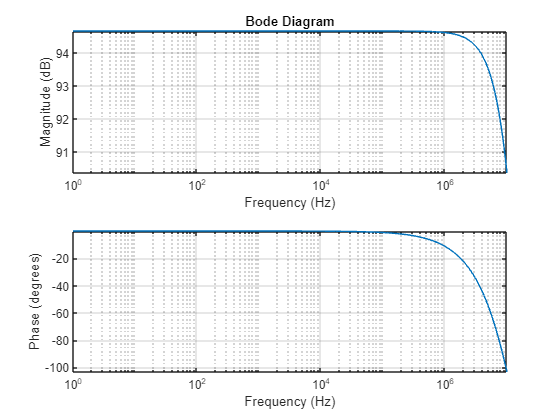

[f,vout] = getSpiceSimulation("C:\Users\lastline\Documents\ltSpice\AT-4.net", "V(vout)", ...
                "Rf1",Rf1, "Cf",Cf, ...
                "R12",R12, "Rrp",R_rp, "Rf2",Rf2, "Crp",rpPwm_CAdditionalFilter);
bode_fromRaw(f, vout);

## Noise Spectrum

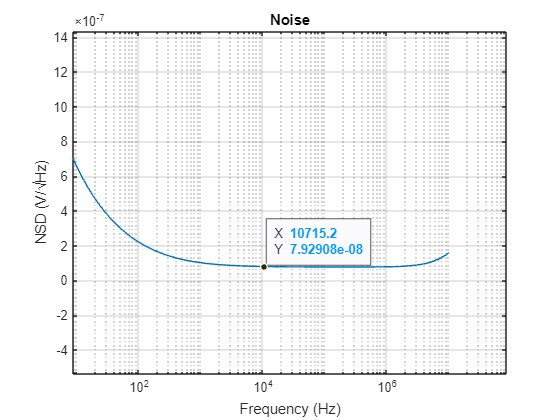

[f,vout] = getSpiceSimulation("C:\Users\lastline\Documents\ltSpice\AT-4_noise.net", "V(onoise)", ...
                "Rf1",Rf1, "Cf",Cf, ...
                "R12",R12, "Rrp",R_rp, "Rf2",Rf2);
plotNoise(f, vout);

## Variable gain

The final circuit should have a variable gain, setted by the FPGA. This would mean that one of the amplification stages should have some way of changing their gain. The gain of stage1 should be kept constant and as high as possible, to reduce the overall noise of the circuit. Stage2 is more suitable, but it could be more troublesome, since it has 2 input signals. And, in any case, modifying the gain would mean that the bandwidth would change too.

We could current-feedback-amplifiers for the variable gain. This type of amplifiers has the bandwidth almost independent from the gain, reducing the problem on the band

Pros

- This type of amplifiers has the bandwidth almost independent from the gain, reducing the problem on the band

Cons

- It might have current absorbtion problems when the common mode voltage gets outside of range. In our case, when the input doesn't match the setpoint, the input would be saturated, and the feedback pin would follow

- Better to use it in the non-inverting configuration => cannot substitue it to the second stage

## Notes

- how to make the variable gain? Is it worth it? Relay, noninverting amplifier (changing lower resistor); using current amplifier, whose band does not depend on amplification

- parallel of resistors on second stage: is it necessary to keep the parallel to 200? the high-band attenuation seems better with a higher parallel (the pole between the parallel of resistors and the parasitic capacitance help to filter the signal, and it doesn't get that close to our band of interest). Also, the noise is better (wait, how? shouldn't higher resistors have higher noise?)

- where to add the connection to the circuit? Could other signals be necessary?

- How to connect to the "digital" pin of the redPitaya? can we use just a simple wire? The signal is just constant/almost constant